# Lagged regressors

Oftentimes, we want to capture the impact on sequential observations (e.g. choices across trials, spiking activity across time bins) of previous events (e.g. previous choices/outcomes, spiking activity in previous time bins). For this purpose we need to add *lagged regressors*, that is regressors which depend on the value of a certain variable with a certain lag with respect to the observations. In GUMs this can be done easily by using the `lag()` operator when declaring the model formula. `lag(x)` simply represents the same variable x with a lag of one observation - i.e. `lag(response)` simply corresponds to the previous response. You can capture different types of lagged regressors using the different options that we introduce below and then illustrate in the different examples in the rest of the tutorial:

- you can include the same regressors at different lags using the `Lags` option, i.e. `lag(response; Lags=1:10)`.

- you can use basis functions (typically exponential or raised cosine) for the weights as a function of lag by using the `basis` option, i.e.  `lag(response; Lags=1:10; basis=exp2)`

- you can define lagged regressors separately for different groups of trials (e.g. subjects, sessions) by using the `group` option, i.e. `lag(response; Lags=1:10; group=session)`

- you can define lagged regressors for a set of variable or split variable by applying the `lag` operator to an expression, i.e. `lag(response+stimulus) or lag(response|outcome; Lags=1:10). `You can impose the same kernel (i.e. same shape across lags) for the different lagged variables by using the` split` option, i.e. `lag(response|outcome; Lags=1:10;split=false).`

### Defining lags

By default `lag(x) `creates a regressor for variable $x$ with lag 1 (i.e. corresponding to the previous observation). You can define the different lags by using the `Lags` option. For example `lag(x;Lags=2)` creates a regressor for $x$ with lag 2; `lag(x;Lags=1,3,5) `creates three regressors with lags respectively of 1, 3 and 5; `lag(x;Lags=1:10)` creates 10 regressors with all possible lags from 1 to 10. Technically, if $x_t$ represents the value of the variable for observation $t$, we introduce a set of $K$ regressors $(x_{t-\text{lag}(k)})$ for $1\leq k \leq K$.

Below we load the data for a monkey performing a motion discrimination task and look for the impact of the 5 previous responses on current choice (on top of the impact of the stimulus).

T = load_online_dataset();

loading csv file from url...done


M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:5)+0');

Prior to estimating model weights, we can visualize the 5 regressors we created by plotting the design matrix (just for the first 50 trials). The diagonals the lagged response regressors indicate that each regressor is just the same as the regressor to its left, shifted by just one trial.

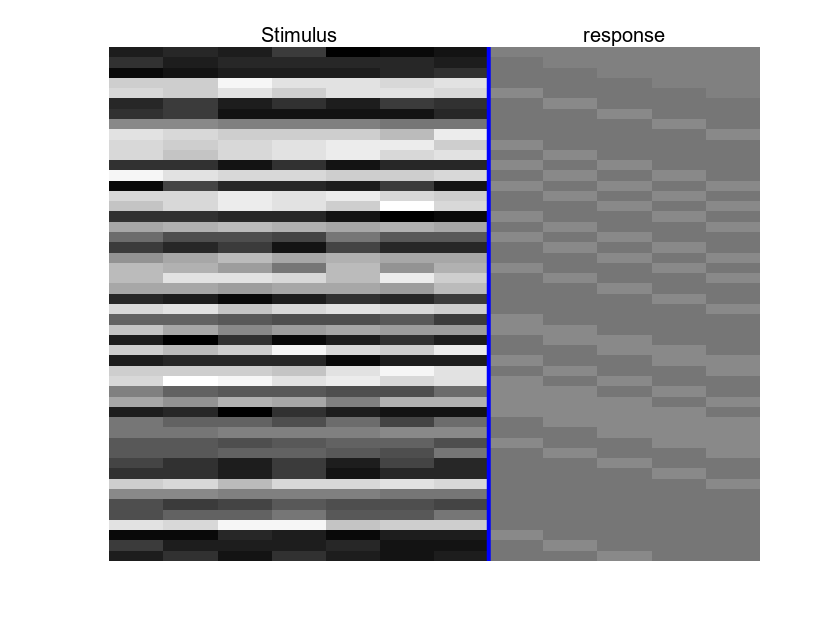

figure;
M.plot_design_matrix(1:50);

Now we estimate model weights and see we get one specific weight for each lag:

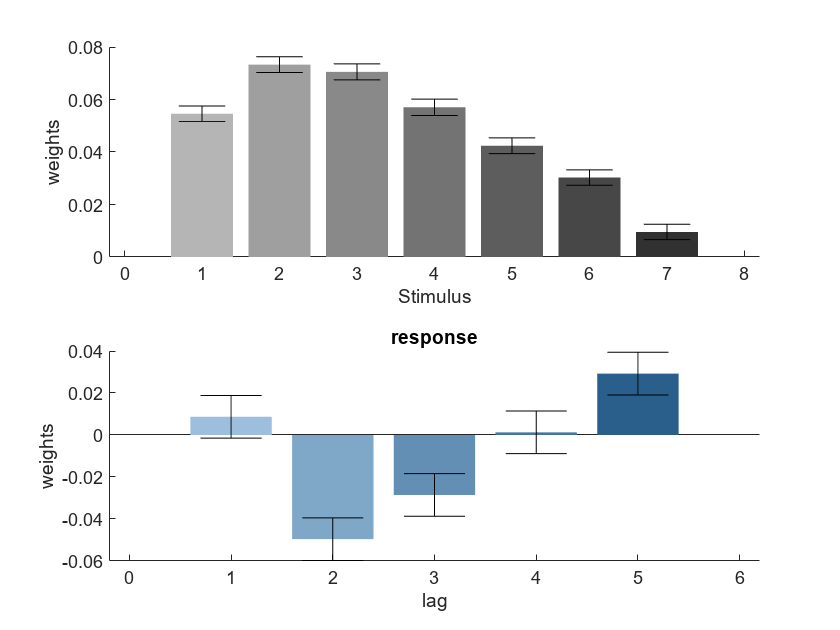

figure;
M.infer('verbose','off').plot_weights;

Here, the negative weights at lags 2 and 3 indicate that the animal tended to respond at the side opposite to the side he responded two trials back and three trials back, while the positive weight at lag 5 indicates that the animal tended to respond at the same side as 5 trials back.

### Basis functions for lagged regressor

If we want to include the impact of a variable across many lags, we soon encounter the problem of statistical power, as the number of weights scales with the number of lags. To circumvent this problem we can use basis functions (exactly as we did to capture [nonlinear mappings](matlab:open('./nonlinear_mapping.mlx'))). Typically we use exponential basis functions, i.e. we assume that the weight for the regressor decays exponentially as a function of lag (or as  sum of exponentials if we use more than one basis function). Mathematically, we constrain $w_k = \sum_{1\leq b\leq B}\exp(-t/\tau_b)$where $w_k$ is the weight for the regressor corresponding to lag $\text{lag}(k)$ and $\tau_b$ represents the decay time constant for the $b$ basis function.

In gum this is declared simply with the `basis` option. For example, `basis=exp` will use a single exponential basis function, `basis=exp3` will use three exponential basis functions and `basis=raisedcosine4` will use 4 raised cosine basis functions.

The decay time constants $\tau_k$ are hyperparameters that can be fitted to the data using `fit()` - see the [tutorial on hyperparameters](matlab:open('./hyperparameters.mlx')) for more details.

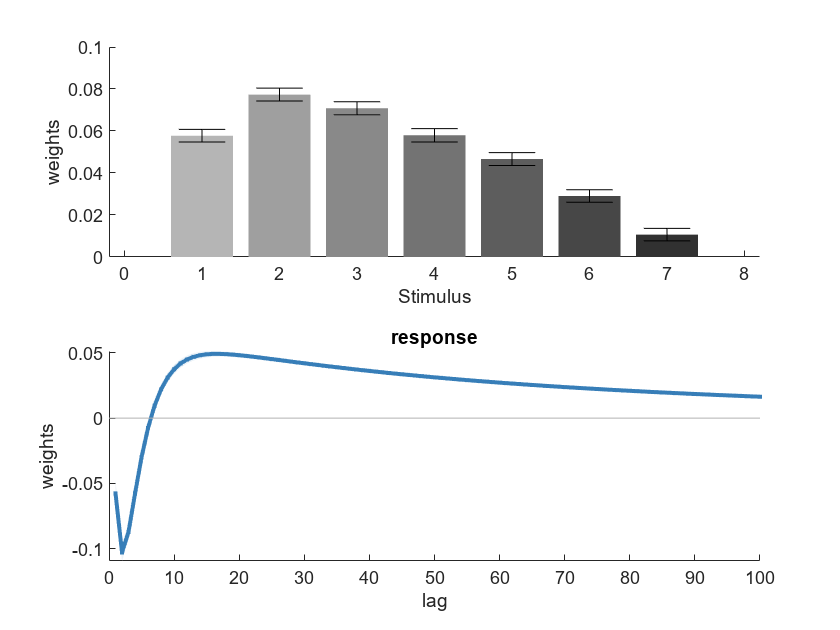

M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:100; basis=exp5)+0');
figure;
M.fit('verbose','off').plot_weights;

### Lagged regressor for different groups of observations

In the previous example we assumed that our dataset represent one single sequence of observations. In many situations your dataset will actually be composed of a series of independent sequences or group of observations  (e.g. each sequence corresponds to a participant, or an experimental session). In this case we don't want lagged regressors to "spill over" different sequences, i.e. if in your dataset the first observations from subject 2 follow the last observations from subject 1, we don't want our lag regressor for these first observations of subject 2 to represent the value of the variables for subject 1 (EXPLAIN BETTER). We will avoid these issues at the boundaries between groups of observations by declaring the grouping variable using the `group `option.

Here, our dataset is composed of different experimental sessions for a single animal. The index of the session is represented in the (guess what?) `session` variable, so we correct our previous model as follow:

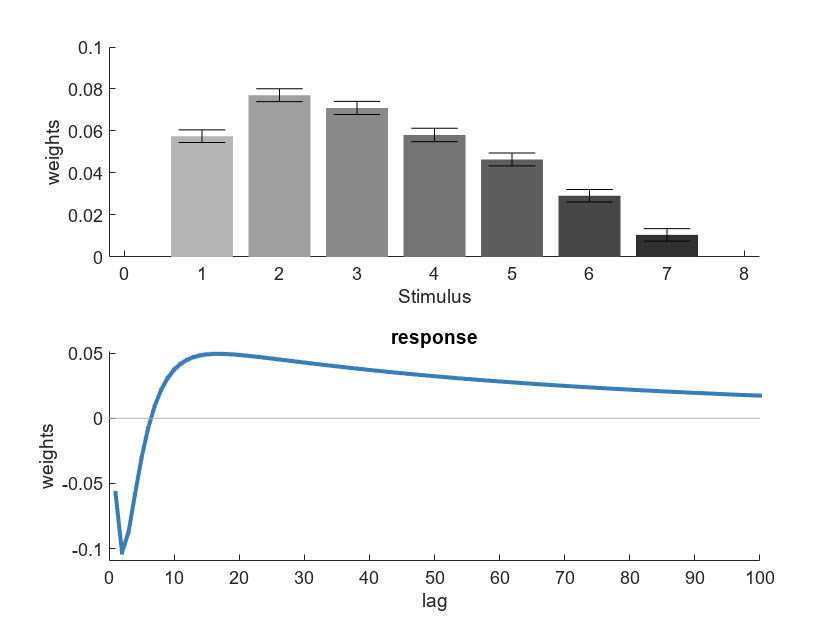

M = gum(T, 'resp ~ Stimulus + lag(response; Lags=1:100; basis=exp5;group=session)+0');
figure;
M.fit('verbose','off').plot_weights;

As you can see, the correction had limited impact of the estimated weights.

### Lagged regressor for sets of variables

Finally, you can also declare jointly lagged regressors for a set of variables. For example `lag(x+y;Lags=1:10) `will create lagged regressors for variable $x$ and for variable $y$, for each lag from 1 to 10. `lag(x|y;Lags=1:10) `will created different lagged regressors of $x$ for each value of the categorical variable $y$. Basically you can apply the `lag()` operator to any valid regressor expression. Here we realize that the impact of the previous responses on the current choice may depend on whether these responses were rewarded or not, so we create a different set of lagged regressors for correct and incorrect responses: 

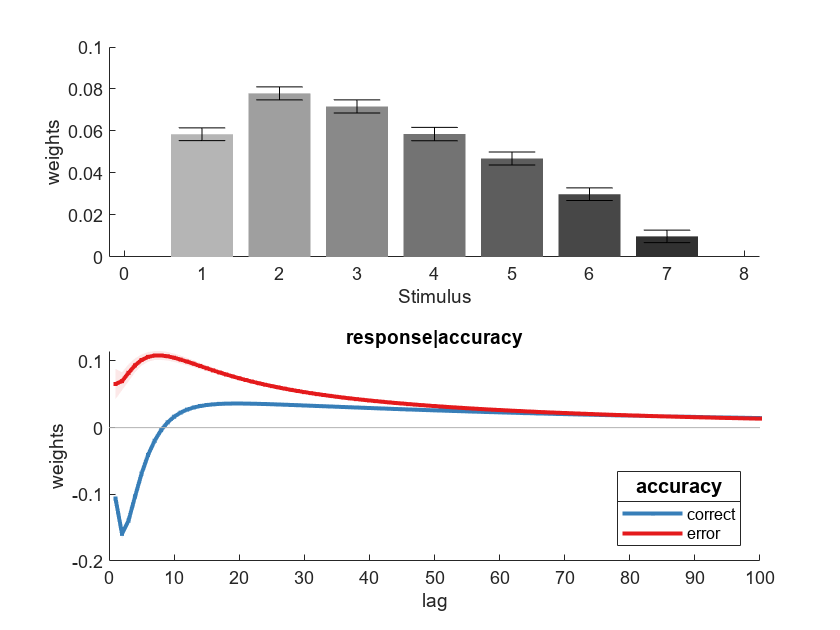

M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:100; basis=exp5;group=session)+0');
figure;
M.fit('verbose','off').plot_weights;

As you can see the propensity to repeat the same response as in previous trials depend drastically on whether that previous response was rewarded or not (although in the exact opposite fashion as one would expect!).

Here we modelled two completely separate set of weights (or kernel) for previously rewarded or unrewarded responses. In some situation however we might expect the shape of this kernel to be similar for the different variables and only vary in magnitude. In this case we can add the option `split=false` when declaring the model. The regression model will now include a common kernel and one magnitude for each variable. Mathematically the weight for variable $i$ at lag $k$ is constrained to be the product of the variable-specific weight $w^{(var)}_i$ and the common kernel $w^{(lag)$ at this lag: $w_{ik}= w^{(var)}_i w^{(lag)}_k$. 

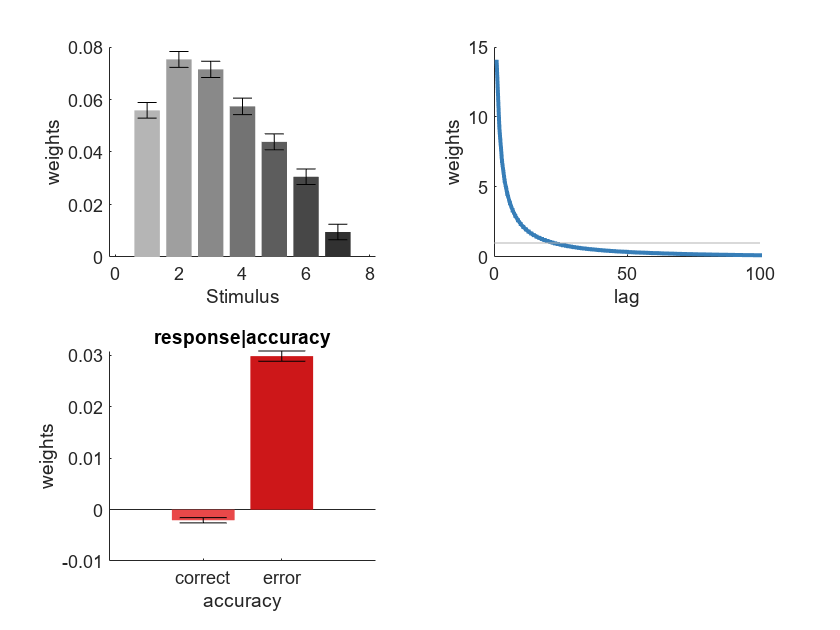

M = gum(T, 'resp ~ Stimulus + lag(response|accuracy; Lags=1:100; basis=exp5;split=false;group=session)+0');
figure;
M.fit('verbose','off').plot_weights;